# LAB 1 - OBJECT COUNTING ON IMAGES

Fromsa T. Negasa, Nadeer Hassan

Photonics for Security, Reliability, and Safety (PSRS)

Medical Biometrics

Yasmina CHENOUNE, Instructor

17th October 2024

clc; clear; close all

## I. Objective

Apply the different concepts of morphological processing for object counting  on a blood cells image

## II. Required tools 

The Image Processing Toolbox of Matlab or Python Image Library. 

## III. Procedure

### 1. Load and show the image 

Read the image bloodcells 

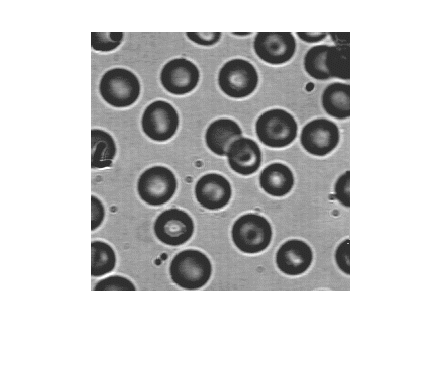

img = imread("BLOODCELLS.bmp");
figure;
imshow(img)

Transform this image into a binary image BW using a thresholding process or a dedicated function of Matlab or Python. 

BW = imbinarize(img, graythresh(img));

Show the two images with titles within the same figure. 

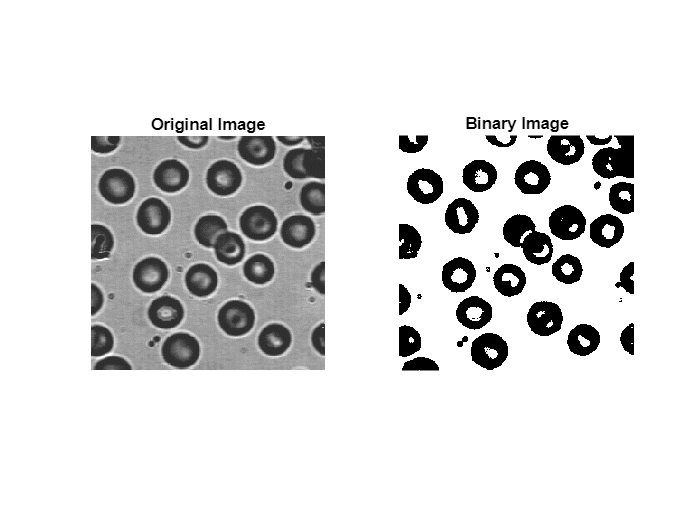

figure;
subplot(1,2,1), imshow(img), title('Original Image');
subplot(1,2,2), imshow(BW), title('Binary Image');

The morphological operator operates on the white pixels in the binary image. What do you observe on the image? What’s the solution of this  problem?

- `Morphological operators typically work on white pixels (foreground), and this could be problematic if the objects are represented by dark pixels.`

- `Solution``: Invert the binary image if the foreground (cells) is dark.`

BW_inv = ~BW;

Show the inverted binary image

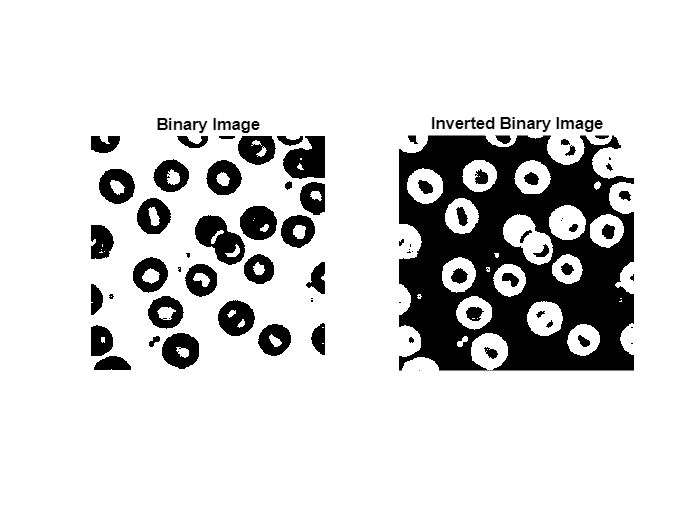

figure;
subplot(1,2,1), imshow(BW), title('Binary Image');
subplot(1,2,2), imshow(BW_inv), title('Inverted Binary Image');

### Erosion

Open and study the help page of the erosion function. 

help imerode

 imerode - Erode image
    This MATLAB function erodes the grayscale, binary, or packed binary
    image I using the structuring element SE.

    Syntax
      J = imerode(I,SE)
      J = imerode(I,nhood)
      J = imerode(___,packopt,m)
      J = imerode(___,shape)

    Input Arguments
      I - Input image
        grayscale image | binary image | packed binary image
      SE - Structuring element
        strel object | offsetstrel object | array of strel objects |
        array of offsetstrel objects
      nhood - Structuring element neighborhood
        matrix of 0s and 1s
      

Choose your appropriate structuring element SE (shape and size) and justify your choice. 

- `Given that the image contains circular cells, the most appropriate structuring element (SE) to use is a ``disk-shaped SE``. This shape matches the geometry of the objects (circular cells and the small debris) in the image and is optimal for preserving their roundness during morphological operations. `

Apply the erosion operator on the binary image BW and Repeat the operation with 3 different sizes of SE.

SE1 = strel('disk', 3); % Small structuring element
SE2 = strel('disk', 5); % Medium structuring element
SE3 = strel('disk', 7); % Large structuring element

eroded1 = imerode(BW_inv, SE1);
eroded2 = imerode(BW_inv, SE2);
eroded3 = imerode(BW_inv, SE3);

Visualize the obtained results, the eroded images. 

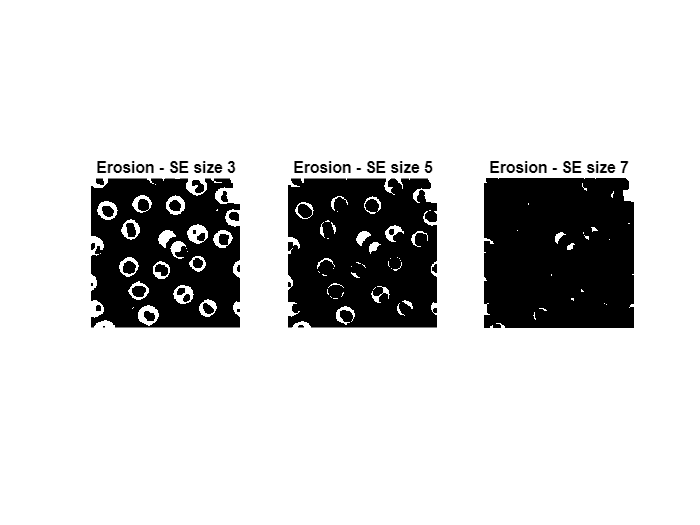

figure;
subplot(1,3,1), imshow(eroded1), title('Erosion - SE size 3');
subplot(1,3,2), imshow(eroded2), title('Erosion - SE size 5');
subplot(1,3,3), imshow(eroded3), title('Erosion - SE size 7');

Discuss the results and explain the observed differences. 

- `The size and shape of the structuring element (SE) impact the results of the erosion. Smaller SEs preserve object details, while larger SEs erode more aggressively. The roundedness is preserved.`

### Dilation 

Open and study the help page of the dilation function. 

help imdilate

 imdilate - Dilate image
    This MATLAB function dilates the grayscale, binary, or packed binary
    image I using the structuring element SE.

    Syntax
      J = imdilate(I,SE)
      J = imdilate(I,nhood)
      J = imdilate(___,packopt)
      J = imdilate(___,shape)

    Input Arguments
      I - Input image
        grayscale image | binary image | packed binary image
      SE - Structuring element
        strel object | offsetstrel object | array of strel objects |
        array of offsetstrel objects
      nhood - Structuring element neighborhood
        matrix of 0s and 1s
      

Choose your appropriate structuring element SE (shape and size). 

- `For the task at hand, where the objects of interest are circular cells, the same is true that the most suitable structuring element (SE) is a ``disk-shaped SE``. Dilation, here, helps to close the holes in the binary image.`

Apply the dilation operator on the binary image BW, and Repeat the operation with 3 different sizes of the SE. 

dilated1 = imdilate(BW_inv, SE1);
dilated2 = imdilate(BW_inv, SE2);
dilated3 = imdilate(BW_inv, SE3);

Visualize the obtained results.

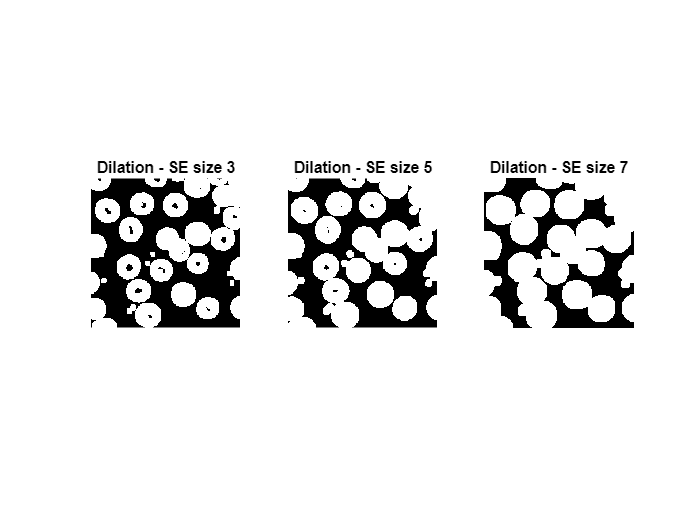

figure;
subplot(1,3,1), imshow(dilated1), title('Dilation - SE size 3');
subplot(1,3,2), imshow(dilated2), title('Dilation - SE size 5');
subplot(1,3,3), imshow(dilated3), title('Dilation - SE size 7');

Discuss the results and explain the observed differences

- `Dilation enlarges objects. Using larger structuring elements increases the object’s size, filling gaps between objects.  `

### Improvement

Are erosion and dilation operators sufficient to extract all the cells with a good precision? 

- `No,these fundamental morphological operations alone are not enough. A combination of the two such as by opening or closing, or advanced techniques like watershed segmentation might be required.`

Which solution do you propose to improve the segmentation results? 

- `Opening, with a structuring element larger that the maximum debris but smaller than the smallest cell, would be ideal to remove the debris. Then, a closing operation or imfill can be used to close the hole in the cells.`

Give a solution and test it on your image

- `We proposed the following preprocessing procedure. It helped us to try different operations in different sequence with different argument. After try and error method, we obtaind a better result with the following setting.`

dbtype('preProcess.m')


1     function processedImage = preProcess(imageFilename)
2     
3         % Step 1: Read the input image
4         img = imread(imageFilename);
5         figure; imshow(img); title('Original Image');
6     
7         % Step 2: Apply median filtering
8         filterSize = 4;
9         filtImg = medfilt2(img, [filterSize filterSize]);
10        figure; imshow(filtImg); title('Filtered Image');
11    
12        % Step 3: Convert to binary image using Otsu's thresholding
13        BW = imbinarize(filtImg, graythresh(img));
14        
15        % Step 4: Invert the binary image
16        BW_inv = ~BW;
17        figure; imshow(BW_inv); title('Inverted Binary Image');
18    
19        % Step 5: Fill holes in the binary image
20        BW_filled = imfill(BW_inv, "holes");
21        figure; imshow(BW_filled); title('Filled Binary Image');
22    
23        % Step 6: Apply morphological opening (remove small objects)
24        BW_open = imopen(BW_filled, strel('disk', 2));
25        figure; im

Call the function.

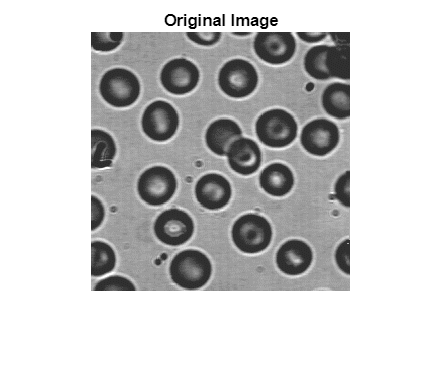

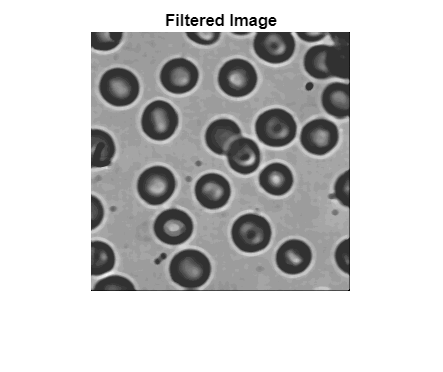

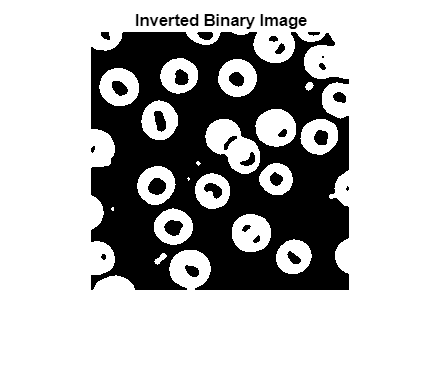

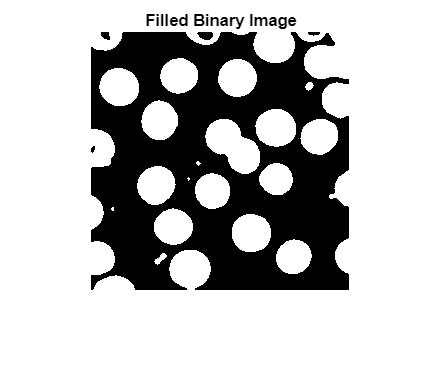

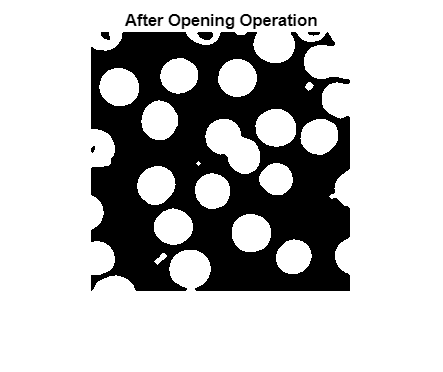

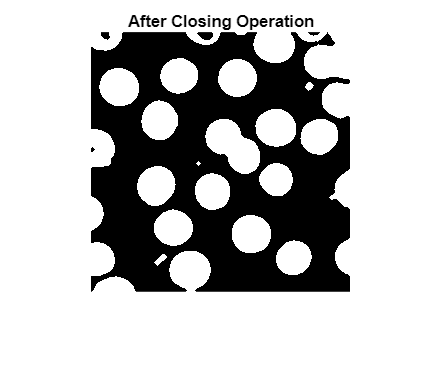

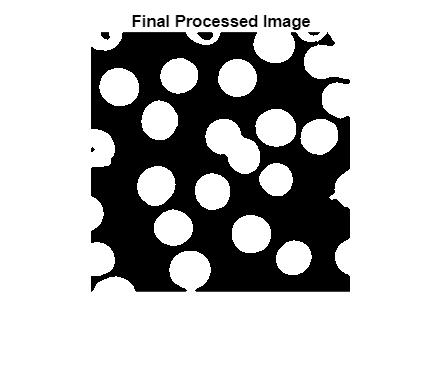

 processedImage = preProcess('BLOODCELLS.bmp');

### Label connected components and counting 

Find the appropriate function for labeling the image objects. 

help bwlabel

 bwlabel - Label connected components in 2-D binary image
    This MATLAB function returns the label matrix L that contains labels for
    the 8-connected objects found in BW.

    Syntax
      L = bwlabel(BW)
      L = bwlabel(BW,conn)
      [L,n] = bwlabel(___)

    Input Arguments
      BW - Binary image
        2-D numeric matrix | 2-D logical matrix
      conn - Pixel connectivity
        8 (default) | 4

    Output Arguments
      L - Label matrix
        matrix of nonnegative integers
      n - Number of connected objec

Use this function to label the segmented objects obtained after the  enhancement step. 

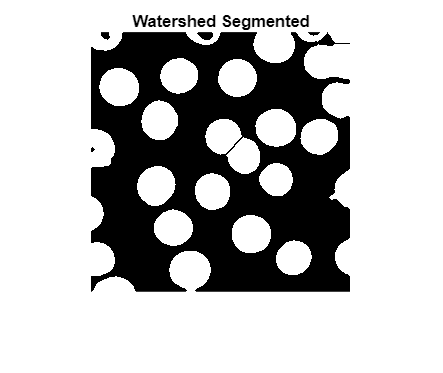

imSegmented = watershedSegmentation(processedImage);
figure; imshow(imSegmented); title('Watershed Segmented')

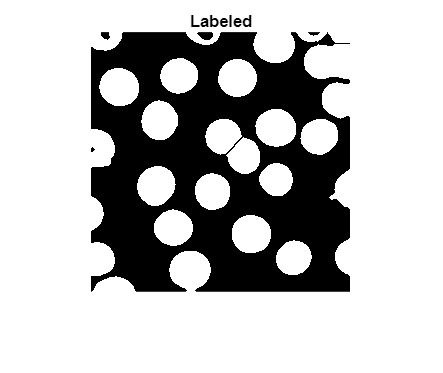

[connectedComponents, TotalCells] = bwlabel(imSegmented);
figure; imshow(connectedComponents); title('Labeled')

 How many cells did you obtain? 

disp("Total cell obtained: " + TotalCells)

Total cell obtained: 28


Show the labelled cells using different colors. 

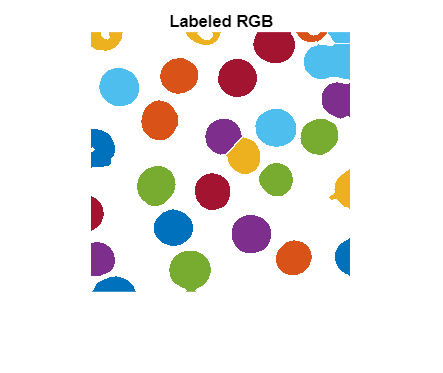

imLabeledRGB = label2rgb(connectedComponents, 'lines', 'white', 'shuffle');
figure; imshow(imLabeledRGB); title('Labeled RGB')

Extract the contours of all the segmented cells and superimpose them  on the original image. 

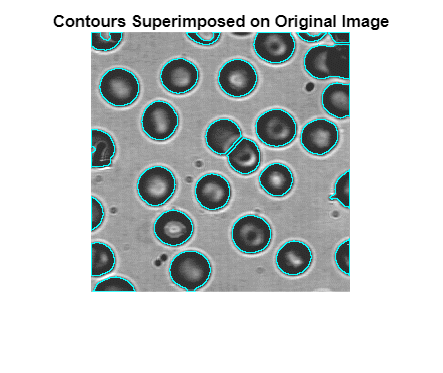

contours = bwperim(connectedComponents, 8);

superimposed = imoverlay(img, contours, "cyan"); % cyan contours
figure;
imshow(superimposed), title('Contours Superimposed on Original Image');

Open and study the help page of the regionprops function of Matlab or the equivalent function on Python. 

help regionprops

 regionprops - Measure properties of image regions
    The regionprops function measures properties such as area, centroid, and
    bounding box, for each object (connected component) in an image.

    Syntax
      stats = regionprops(BW,properties)
      stats = regionprops(CC,properties)
      stats = regionprops(L,properties)
      stats = regionprops(regions,I,properties)
      stats = regionprops(outputFormat,___)

    Input Arguments
      BW - Binary image
        logical array
      CC - Connected components
        structure
      L - Label image
        numeric array 

Use this function to perform three measurements on one or more  objects (areas, perimeter…) 

cellProps = regionprops("table", connectedComponents, "Area", "Perimeter", "Centroid")

cellProps = 28×3 table
    Area        Centroid        Perimeter
    ____    ________________    _________

     447    15.038     9.396     97.654  
     757     11.14    117.19     112.04  
     320    5.7406    180.94     76.896  
     679    11.015    226.72     95.768  
     492     23.87    253.13      97.29  
    1196    28.829    55.604     119.85  
    1147    65.732     153.7     118.19  
    1126    69.108    89.014     116.78  
    1098    82.947    195.38     115.01  
    1052    88.702    44.372     112.38  
    1289    99.621    237.88      129.7  
     239    112.83    6.6862     89.583  
     991    122.13    159.62      108.9  
     941    132.07    104.33     108.75  
    1158    147.01    46.511     117.53  
     873     154.2    125.25     105.38  


Show in one figure the largest cell and on another figure the smallest one.

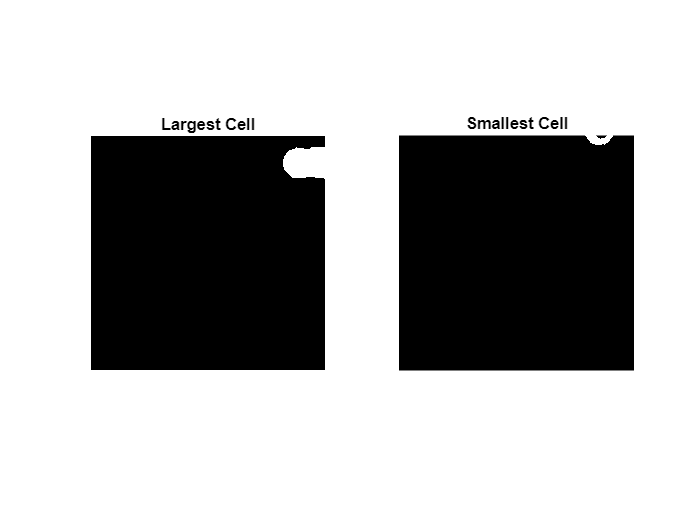

% Get the indices
allAreas = [cellProps.Area];
[~, largestIdx] = max(allAreas);
[~, smallestIdx] = min(allAreas);

% Display largest and the smallest
largestCellMask = ismember(connectedComponents, largestIdx);
smallestCellMask = ismember(connectedComponents, smallestIdx);

figure;
subplot(121); imshow(largestCellMask), title('Largest Cell');
subplot(122); imshow(smallestCellMask), title('Smallest Cell');

The above figure is a little bit misleading since that is not the actuall truth. The indicated labels are, for the largest cell, an overlapping of two cells that were segmented as one, and for the smallest cell, a cropped part of a cell on the border of the image. Hence, we used a visualization approach to show the order of the area of the labels to help the expert decide the largest and smallest cell from the overall perspective. 

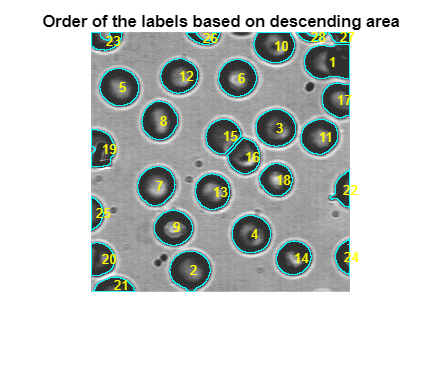

% Sort the areas in descending order and get the indices
[sortedAreas, sortIndexes] = sort(allAreas, 'descend');

% Step 4: Overlay the numbers on the image based on sorted area
figure; imshow(superimposed); title('Order of the labels based on descending area') % hold on;
for i = 1:TotalCells
    % Get the index of the current object in the sorted order
    currentLabel = sortIndexes(i);
    
    % Get the centroid of the current object from the table
    centroid = cellProps(currentLabel, :).Centroid;
    
    % Overlay the number corresponding to the object's order in the sorted list
    text(centroid(1), centroid(2), num2str(i), 'Color', 'Yellow', 'FontSize', 8);
end

Alternative way, to apprach this problem using: Circular Hough Transform. 

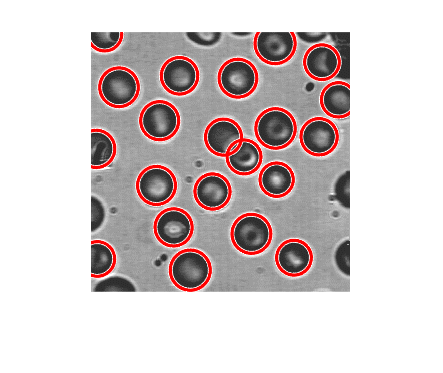

[centers, radii] = imfindcircles(processedImage, [15 40], ...
                                     'ObjectPolarity', 'bright', ...
                                     'Sensitivity', 0.88, ...
                                     'EdgeThreshold', 0.25);

% Display original image and detected circles
figure;
imshow(img, 'Parent', gca);
hold on;
viscircles(centers, radii, 'Color', 'r');
hold off;